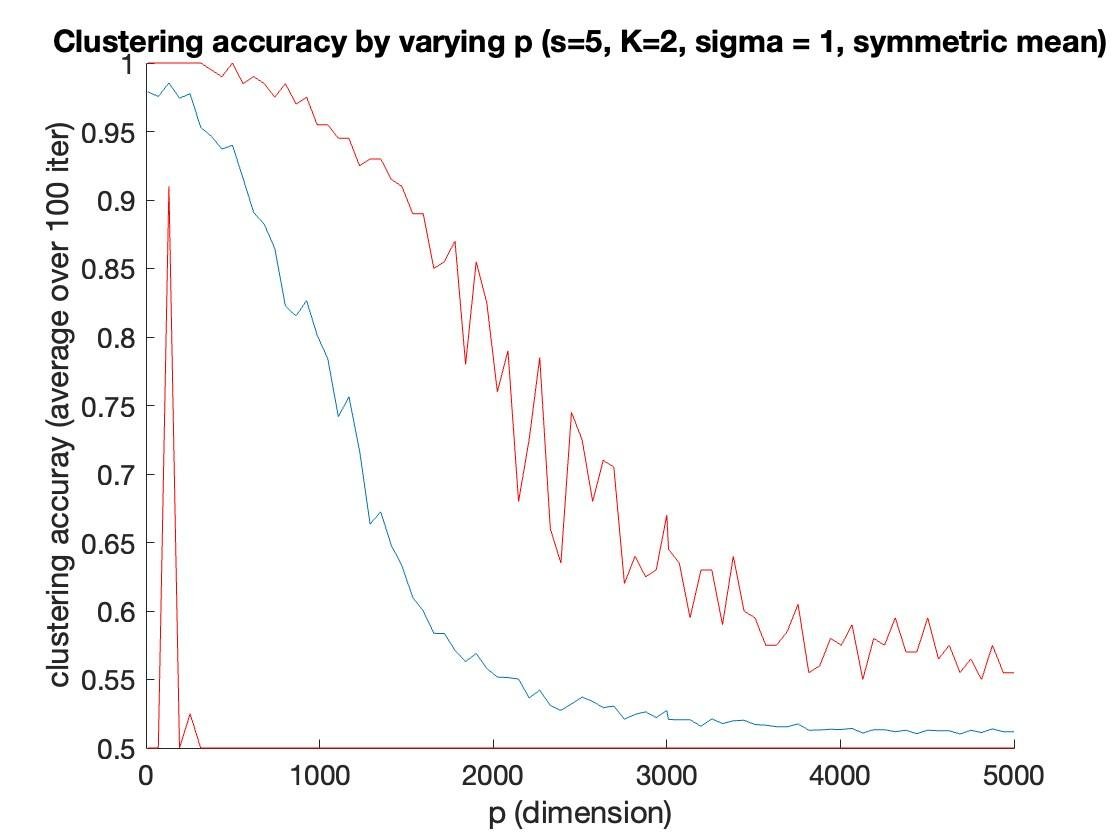

iterative thresholding

1. run  SDP k-means. re-arrange the rows to get $X_{{\mathcal{G}}_1}$and $X_{{\mathcal{G}}_2}$.

2. Calculate group sample means:

                
$$\bar{X}_{{\mathcal{G}}1} := {n{{\mathcal{G}}_1}}^{-1} 1^\top X{{\mathcal{G}}_1}
\\
\bar{X}_{{\mathcal{G}}_2} := {n{{\mathcal{G}}_2}}^{-1} 1^\top X{{\mathcal{G}}_2}$$


3. guess the non-zero entries: make a zero-one vectors by thresholding each element of the group sample mean by


$$ c_1 = \sigma \sqrt{ \frac{2 \log p}{{n_{{\mathcal{G}}1}}}}, \quad c_2 = \sigma \sqrt{\frac{2 \log p}{{n_{{\mathcal{G}}_2}}}} $$


4. Apply thresholding to the data matrix (not affinity matrix)

5. Run SDP k-means to the thresholded data

6. iterate 2-5.

n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 3; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);

M = 0.7906

#### p=1200 (accuracy near 0.75)

p = 1200;
rng(1)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);

x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
x_now = x;
A_now = (x_now * x_now')/ n;
Z_now = kmeans_sdp(A_now, K);     

Incorrect number or types of inputs or outputs for function 'svec'.

Error in kmeans_sdp (line 45)
Auxt(:,1)=svec(blk(1,:), eye(n),1);

cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);
cluster_acc_before_thres = max( ...
            mean(cluster_true == cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            );

fprintf("p = %i, acc before thres: %f", p, cluster_acc_before_thres);

for iter = 1:n_iter
    fprintf("%i th thresholding", iter)
    % 1. estimate cluster means
    n_g1_now = sum(cluster_est_now==1);
    n_g2_now = sum(cluster_est_now==-1);
    
    %question: accumulated thresholding?
    % i think the answer is no; wrongly deleted entry should have a second
    % chance
    x_now_g1 = x((cluster_est_now == 1), :); % or x((cluster_est_now == 1), :)
    x_now_g2 = x((cluster_est_now == -1), :);

    x_bar_g1 = mean(x_now_g1, 1);  
    x_bar_g2 = mean(x_now_g2, 1);
    
    % 2. threshold the data matrix
    %c_1 = sigma * sqrt(2 * log(p) / n_g1_now);
    %c_2 = sigma * sqrt(2 * log(p) / n_g2_now);
    c = sqrt(2 * log(p) ) * sqrt(sigma^2*(1/n_g1_now + 1/n_g2_now));
    %thresholder_vec_g1 = abs(x_bar_g1) > c_1;
    %thresholder_vec_g2 = abs(x_bar_g2) > c_2;
    thresholder_vec = abs(x_bar_g1 - x_bar_g2) > c;
    fprintf("%i entries survived \n",sum(thresholder_vec))
    find(thresholder_vec)
   

    x_tilde_g1 =  x_now_g1 * diag(thresholder_vec);
    x_tilde_g2 =  x_now_g2 * diag(thresholder_vec);

    % 3. apply SDP k-means
    x_now = zeros([n,p]);
    x_now((cluster_est_now == 1), :)  = x_tilde_g1;
    x_now((cluster_est_now == -1), :)  = x_tilde_g2;
    A_now = (x_now * x_now')/ n;
    Z_now = kmeans_sdp(A_now, K);     
    cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);

    cluster_acc = max( ...
            mean(cluster_true == cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            )
end

1 th thresholding

5 entries survived in G1


ans =      1     3     5     6     8


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes=1.0,  maxresidual < 1.00e-06

cluster_acc = 0.9450

2 th thresholding

11 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10   277


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=6.10e-06,dualfeasorg=6.65e-06

cluster_acc = 0.9850

3 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

4 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

5 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

6 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

7 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

8 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

9 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

10 th thresholding

10 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc = 0.9850

#### p=1500 (accuracy near 0.65)

p = 1500;
n_iter = 4;
rng(15)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);

x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
x_now = x;
A_now = (x_now * x_now')/ n;
Z_now = kmeans_sdp(A_now, K);     
cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);
cluster_acc_before_thres = max( ...
            mean(cluster_true == cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            );

fprintf("p = %i, acc before thres: %f", p, cluster_acc_before_thres);

p = 1500, acc before thres: 0.675000

for iter = 1:n_iter
    fprintf("%i th thresholding", iter)
    % 1. estimate cluster means
    n_g1_now = sum(cluster_est_now==1);
    n_g2_now = sum(cluster_est_now==-1);
    
    %question: accumulated thresholding?
    % i think the answer is no; wrongly deleted entry should have a second
    % chance
    x_now_g1 = x((cluster_est_now == 1), :); % or x((cluster_est_now == 1), :)
    x_now_g2 = x((cluster_est_now == -1), :);

    x_bar_g1 = mean(x_now_g1, 1);  
    x_bar_g2 = mean(x_now_g2, 1);

    % 2. threshold the data matrix
    c_1 = sigma * sqrt(2 * log(p) / n_g1_now);
    c_2 = sigma * sqrt(2 * log(p) / n_g2_now);

    thresholder_vec_g1 = abs(x_bar_g1) > c_1;
    thresholder_vec_g2 = abs(x_bar_g2) > c_2;
    fprintf("%i entries survived in G1\n",sum(thresholder_vec_g1))
    find(thresholder_vec_g1)
    fprintf("%i entries survived in G2\n",sum(thresholder_vec_g2))
    find(thresholder_vec_g2)

    x_tilde_g1 =  x_now_g1 * diag(thresholder_vec_g1);
    x_tilde_g2 =  x_now_g2 * diag(thresholder_vec_g2);

    % 3. apply SDP k-means
    x_now = zeros([n,p]);
    x_now((cluster_est_now == 1), :)  = x_tilde_g1;
    x_now((cluster_est_now == -1), :)  = x_tilde_g2;
    A_now = (x_now * x_now')/ n;
    Z_now = kmeans_sdp(A_now, K);     
    cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);

    cluster_acc_now = max( ...
            mean(cluster_true == cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            )
end

1 th thresholding

3 entries survived in G1


ans =            3           4        1323


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes = 1.0,  maxresidual < 1.00e-04

cluster_acc_now = 0.7750

2 th thresholding

8 entries survived in G1


ans =            1           3           4           5           8          10         638        1323


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc_now = 0.9700

3 th thresholding

11 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10   638


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc_now = 0.9950

4 th thresholding

11 entries survived in G1


ans =      1     2     3     4     5     6     7     8     9    10   638


10 entries survived in G2


ans =      1     2     3     4     5     6     7     8     9    10


cluster_acc_now = 0.9950

#### p=2500 (accuracy near 0.55) - need discussion

p = 2500;
n_iter = 4;
rng(15)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);

x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
x_now = x;
A_now = (x_now * x_now')/ n;
Z_now = kmeans_sdp(A_now, K);     

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);
cluster_acc_before_thres = max( ...
            mean(cluster_true == cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            );

fprintf("p = %i, acc before thres: %f", p, cluster_acc_before_thres);

p = 2500, acc before thres: 0.545000

for iter = 1:n_iter
    fprintf("%i th thresholding", iter)
    % 1. estimate cluster means
    n_g1_now = sum(cluster_est_now==1);
    n_g2_now = sum(cluster_est_now==-1);
    
    %question: accumulated thresholding?
    % i think the answer is no; wrongly deleted entry should have a second
    % chance
    x_now_g1 = x((cluster_est_now == 1), :); % or x((cluster_est_now == 1), :)
    x_now_g2 = x((cluster_est_now == -1), :);

    x_bar_g1 = mean(x_now_g1, 1);  
    x_bar_g2 = mean(x_now_g2, 1);
    
    % 2. threshold the data matrix
    %c_1 = sigma * sqrt(2 * log(p) / n_g1_now);
    %c_2 = sigma * sqrt(2 * log(p) / n_g2_now);
    c = sqrt(2 * log(p) ) * sqrt(sigma^2*(1/n_g1_now + 1/n_g2_now));
    %thresholder_vec_g1 = abs(x_bar_g1) > c_1;
    %thresholder_vec_g2 = abs(x_bar_g2) > c_2;
    thresholder_vec = abs(x_bar_g1 - x_bar_g2) > c;
    fprintf("%i entries survived \n",sum(thresholder_vec))
    find(thresholder_vec)
   

    x_tilde_g1 =  x_now_g1 * diag(thresholder_vec);
    x_tilde_g2 =  x_now_g2 * diag(thresholder_vec);

    % 3. apply SDP k-means
    x_now = zeros([n,p]);
    x_now((cluster_est_now == 1), :)  = x_tilde_g1;
    x_now((cluster_est_now == -1), :)  = x_tilde_g2;
    A_now = (x_now * x_now')/ n;
    Z_now = kmeans_sdp(A_now, K);     
    cluster_est_now = estimate_cluster(Z_now, rounding, n, cluster_true);

    cluster_acc = max( ...
            mean(cluster_true == cluster_est_now), ...
            mean(cluster_true == -cluster_est_now) ...
            )
end

1 th thresholding

2 entries survived 


ans =      4     5


  breakyes = 1.0,  maxresidual < 1.00e-04

cluster_acc = 0.8900

2 th thresholding

10 entries survived 


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes=1.0,  maxresidual < 1.00e-06

cluster_acc = 0.9950

3 th thresholding

10 entries survived 


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes=1.0,  maxresidual < 1.00e-06

cluster_acc = 0.9950

4 th thresholding

10 entries survived 


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes=1.0,  maxresidual < 1.00e-06

cluster_acc = 0.9950

Under two-cluster setting (K=2), the lowest clustering accuracy is 0.5, where all samples are clustered into one cluster.

Then in the first cluster, signal is canceled out because we have symmetric means. Therefore every entry is zeroed out.